# **This project intends to encode a JPEG grayscale photo and decode it to see the result.**

# **1- Encoding**

## **JPEG encoding and decoding**

image = imread("lana.jpg");
disp("The original photo:")

The original photo:


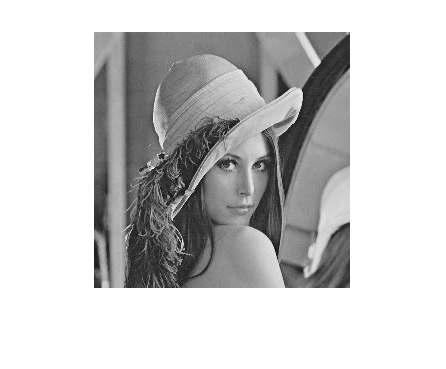

imshow(image)

[W,H] = size(image); 

[dict, encoded, compressionRat] = JPEG_encode(image);
decodedIm = JPEG_decode(dict, encoded, W, H);
decodedIm = uint8(decodedIm);
disp("The decoded photo:")

The decoded photo:


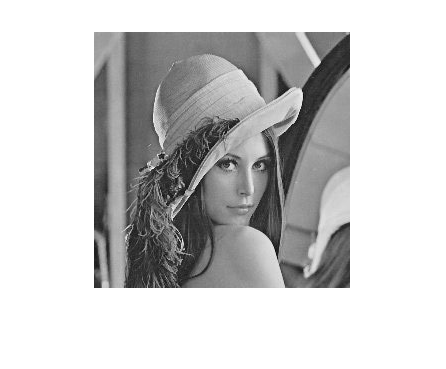

imshow(decodedIm);

disp("compression Ratio: ")

compression Ratio: 


disp(compressionRat);

  332.7165



## **Video encoding and decoding**

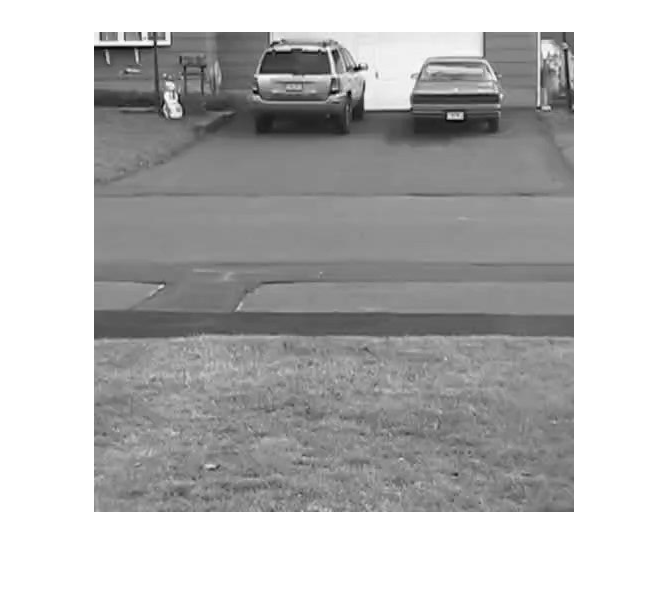

vid = VideoReader('video.mp4');     % Read video file
ref = read(vid , 1);                % Identfing reference frame
ref = rgb2gray(ref);                
[dict, encoded, compressionRat] = JPEG_encode(ref);     % JPEG encoding reference frame
decodedRef = JPEG_decode(dict, encoded, 480, 480);      % JPEG decoding reference frame
decodedRef = uint8(decodedRef);
imshow(decodedRef)


v=VideoWriter('out.avi');
sum = 0;    % Sum of decoded frames lengths
open(v);    
for i = 2 : vid.NumFrames
    
    curr = read(vid , i);
    curr = rgb2gray(curr);

    motionVectors = MotionEstimate(ref,curr);               % Generate motion vectors
    prediction = MotionCompensearion(ref, motionVectors);   % generating the prediction

    curr = int32(curr);
    prediction = int32(prediction);
    
    diff = curr - prediction;                               % getting the difference
    [dict, encodedD, compressionRat] = JPEG_encode(diff);   % JPEG encode difference
    decodedDiff = JPEG_decode(dict, encodedD, 480, 480);    % JPEG decode difference
    
    sum = sum + length(encodedD);   % Updating sum of lengths of decoded frames
    
    prediction2 = MotionCompensearion(ref, motionVectors);  % Prediction in decoder
    prediction2 = int32(prediction2);
    
    
    result = prediction2 + decodedDiff;     % Regenerating the frame
    result = uint8(result);
    
    writeVideo(v, result);                  % Enclude the frame in the output video
end
close(v);

Compression Ratio

expLen = vid.NumFrames * vid.Height * vid.Width *8;     % Expected length of the actual video
comprate= (expLen/sum)*100;    % Compression ratio
disp('Compression ratio = ');

Compression ratio = 


disp(comprate);

  512.0368



disp('%');

%


# **3- Functions**

## **Motion Estimation function**

function [motion_vectors] = MotionEstimate(ref, curr)
    block_size = 16;
    search_area = 4;
    [len, width] = size(curr);
    motion_vectors = {};

    for i = 1 : block_size : len
        for j = 1 : block_size : width
            if (i + block_size - 1 > len || j + block_size - 1 > width)
                continue; % Skip the indecies out of range
            end
            block = curr(i : i + block_size - 1, j : j + block_size - 1);

            half_region = search_area/2; % Search size should be even (left space = right space)
            max = 0; % will be used to get maximum correlation between other px

            for h1 = -half_region : half_region
            for h2 = -half_region : half_region
                xi = i + h1;
                xf = xi + block_size - 1;

                yi = j + h2;
                yf = yi + block_size - 1;

                if xi < 1 || xf > len || yi < 1 || yf > width
                    continue; % Skip the indecies out of range
                end
                corr = calcCorr(block, ref(xi : xf, yi : yf));

                % Update max corr and its new x and x
                if corr >= max
                    newX = h1; % new X position
                    newY = h2; % new Y position
                    max = corr;
                end
            end
            end
            motion_vectors{end + 1} =[newX newY];
        end
    end
end


## Correlation function

function corr = calcCorr(blk1, blk2)
    [L1, W1] = size(blk1);
    corr = 0;

    for i = 1 : L1
        for j = 1 : W1
            corr = corr + (blk1(i, j) * blk2(i, j));
        end
    end

end

## Motion Compensearion function

function P = MotionCompensearion(ref, motion_vectors)
    size_of_block = 16;
    [len, wid] = size(ref); 
    P = zeros([len, wid]);
    idx = 1;

    for i = 1 : size_of_block : len
        for j = 1 : size_of_block : wid
            xi = i; % initial x
            xf = i + size_of_block - 1; % final x
            yi = j; % initial y
            yf = j + size_of_block - 1; % final x

            if(idx > length(motion_vectors))
                continue; % Skip the indecies out of range
            end
            motion_vector = cell2mat(motion_vectors(idx));

            r = motion_vector(1);
            c = motion_vector(2);

            if (xf > len || yf > wid || xf + r > len || yf + c > wid)
                continue; % Skip the indecies out of range
            end
            P(xi : xf, yi : yf) = ref(xi + r : xf + r, yi + c : yf + c);
            
            idx = idx + 1;
        end
    end
end

## JPEG encoding function

function [dict, encoded, compressionRat] = JPEG_encode(image)

[W,H] = size(image);        % Defining the size of the photo. Assuming that W and H are devisable by 8.
q1 = 1; q2 = 2;             % This is the input of the QuantizationTable function and takes either the value (1 or 2).
endblock = 10000;           % This variable defines the end of the block using a high value.
Compressed = [];            % Defining the compressed array which will be sent.

for u = 1:W/8
    for v = 1:H/8
        Block = image(((u-1)*8 + 1):u*8 , ((v-1)*8 + 1):v*8);   % defining the block to be 8x8 pixles.
        Block = double(Block);                                  % casting the pixles to be of double values
        DCT = Block8_DCT(Block);                                % using DCT on the block
        Quantize = round(DCT./QuantizationTable(q1));
        ZZ = ZigZag(Quantize);                              % applying the zigzag method
        Compressed = [Compressed Run_Length(ZZ) endblock];      % concatunating the outputs of every run length operation to acheive the compressed array    
    end
end

uniq = unique(Compressed);
[freq, symbols] = histcounts(Compressed(:),[uniq 10000]);       % getting the frequancy of each symbol
symbols = uniq;
prop = (1/sum(freq)).*freq;                                     % getting the problability of each symbol
dict = huffmandict(symbols , prop);
encoded = huffmanenco(Compressed , dict);                       % huffman encoding
compressionRat = (W*H*8/length(encoded))*100;                   % getting the compression ratio.

end

## JPEG decoding function

function decodedIm = JPEG_decode(dict, encoded, W, H)

decoded = huffmandeco(encoded , dict);                          % Huffman decoding
decodedIm = zeros(W,H);                                         % initiating the decoded image
handling = [];                                                  % an array to handle the condition if the block length was less than 64
current = 1;
endblock = 10000;           % This variable defines the end of the block using a high value.
q1 = 1; q2 = 2;             % This is the input of the QuantizationTable function and takes either the value (1 or 2).


for u = 1:W/8
    for v = 1:H/8
        i = current;
        j = current;
        while decoded(j) ~= endblock                            % checking if we reached the endblock value
            j = j+1;
        end
        block = invRunLength(decoded(i:j-1));                   % applying the inverse run length function on the decoded array 
        if length(block) < 64                                   % handling this error
            handling = decoded(i:j-1);
        end
        block = invZigZag(block , 8);                              % applying th einverse zigzag method on the array to construct an 8x8 block
        block = block .* QuantizationTable(q1);                  % using the QuantizationTable function to apply  decompression.
        block = Block8_IDCT(block);                             % applying IDCT
        decodedIm(((u-1)*8 + 1):u*8 , ((v-1)*8 + 1):v*8) = block;   %constructing the decoded image.
        current = j+1;
    end     
end

decodedIm = round(decodedIm);
decodedIm = cast(decodedIm , 'int32');

end

## **DCT function**

function dct_result=Block8_DCT(block_8)
[R,C]=size(block_8);
%intialize the basis block
basis=zeros(R,C);
if R~=8 || C~=8
    disp('Error in block size');
end
%looping over the size of the basis and size of the input
dct_result=zeros(8,8);
for u=0:7
    for v=0:7
        for x=0:7
            for y=0:7
                % constructing the basis function
                basis(x+1,y+1)=(cos((1/16)*(2*x+1)*u*pi))*(cos((1/16)*(2*y+1)*v*pi));
            end
        end
        % multiplying each pixel to the corresponding basis block and averaging them then storing in dct_result
        dct_result(u+1,v+1)=sum(sum(block_8.*basis));
    end
end
% Now Scaling
dct_result(1,1)=(1/64)*dct_result(1,1);             %The first value in the block /64
dct_result(1,2:8)=(1/32)*dct_result(1,2:8);         %The first row /32
dct_result(2:8,1)=(1/32)*dct_result(2:8,1);         %The first column /32
dct_result(2:8,2:8)=(1/16)*dct_result(2:8,2:8);     % the rest of the block/16
end

## IDCT function

function idct_result=Block8_IDCT(block_8)
[R,C]=size(block_8);
%Intializations
basis=zeros(R,C);
if R~=8 || C~=8
    disp('Error in block size');
end
%looping over the size of the basis and size of the input
idct_result=zeros(8,8);
for u=0:7
    for v=0:7
        for x=0:7
            for y=0:7
                %constructing the basis block
                basis(x+1,y+1)=(cos((1/16)*(2*x+1)*u*pi))*(cos((1/16)*(2*y+1)*v*pi));
            end
        end
        % multiplying each value of encoded_block to the corresponding
        % basis block and summing the result and storing it in the result_Idct block
        idct_result=idct_result+block_8(u+1,v+1)*basis;
    end
end
end

## Quantization Table function

function Table = QuantizationTable(x)
if x==1  % for Low compression
    Table = [1 1 1 1 1 2 2 4
        1 1 1 1 1 2 2 4
        1 1 1 1 2 2 2 4
        1 1 1 1 2 2 4 8
        1 1 2 2 2 2 4 8
        2 2 2 2 2 4 8 8
        2 2 2 4 4 8 8 16
        4 4 4 4 8 8 16 16];
elseif x==2  % for high compression
    Table=[1 2 4 8 16 32 64 128;
        2 4 4 8 16 32 64 128;
        4 4 8 16 32 64 128 128;
        8 8 16 32 64 128 128 256;
        16 16 32 64 128 128 256 256;
        32 32 64 128 128 256 256 256;
        64 64 128 128 256 256 256 256;
        128 128 128 256 256 256 256 256];
else
    disp('Error in choose X');
end
end

## ZigZag scanning function

function out=ZigZag(X)
[~, N]=size(X);
out=zeros(1,N*N);
out(1)=X(1,1);
v=1;
for k=1:2*N-1
    if k<=N
        if mod(k,2)==0
        j=k;
        for i=1:k
        out(v)=X(i,j);
        v=v+1;j=j-1;    
        end
        else
        i=k;
        for j=1:k   
        out(v)=X(i,j);
        v=v+1;i=i-1; 
        end
        end
    else
        if mod(k,2)==0
        p=mod(k,N); j=N;
        for i=p+1:N
        out(v)=X(i,j);
        v=v+1;j=j-1;    
        end
        else
        p=mod(k,N);i=N;
        for j=p+1:N   
        out(v)=X(i,j);
        v=v+1;i=i-1; 
        end
        end
    end
end
end

## Run Length function

function out = Run_Length(X)
lenX = length(X);
y = 1;
out = [];
while y <= lenX
    
    count = 0;
if X(y) ++ 0
    out = [out X(y)];
    y = y+1;
else
        while y <= lenX && X(y) == 0 
        y = y +1;
        count = count + 1;
        end
        out = [out 0 count];
     
end
end
end

## Inverse zigzag Function

function [out] = invZigZag(B,dim)
v = ones(1,dim); k = 1;
out = zeros(dim,dim);
for i = 1:2*dim-1
    C1 = diag(v,dim-i);
    C2 = flip(C1(1:dim,1:dim),2);
    C3 = B(k:k+sum(C2(:))-1);
    k = k + sum(C2(:));
    if mod(i,2) == 0
       C3 = flip(C3);
    end
    C4 = zeros(1,dim-size(C3,2));
    if i >= dim
       C5 = cat(2,C4, C3); 
    else       
        C5 = cat(2,C3,C4);
    end
    C6 = C2*diag(C5);
    out = C6 + out;
end
end

## Inverse Run Length Function

function out = invRunLength(X)
y = 1;
out = [];
while y <= length(X)
    if X(y) == 0
        out = [out zeros(1, X(y+1))];
        y = y +1;
    else
        out = [out X(y)];
        
    end
    y = y +1;
end
end